# 量子XY模型

[Twisted-Boundary-Condition Formalism for Thermal Transport and an Application to the One-Dimensional XY Spin Chain | Proceedings of the 29th International Conference on Low Temperature Physics (LT29)](https://journals.jps.jp/doi/10.7566/JPSCP.38.011175)


$$H=-\sum_{j=1}^L\left( J_xS_j^xS_{j+1}^x+J_yS_j^yS_{j+1}^y-H_zS_j^z\right)



$$



$$=-\frac{J_x+J_2}{4}\sum_{j=1}^L\left(\frac{1+\gamma}{2}\sigma_j^x\sigma_{j+1}^x+\frac{1-\gamma}{2}\sigma_j^y\sigma_{j+1}^y -h\sigma_j^z\right)$$


加上周期性边界条件

clear;
tic;
% 参数设置
N = 6;          % 6个自旋
beta = 10;     % 逆温度
L = N;

delta_lambda = 1e-3; % 扭曲参数微扰

N_points = 100;
Jx = linspace(2, 6, N_points);
B_field = linspace(0, 4, N_points+1);
% Jx = 2;
% B_field = 0;
gamma = zeros(length(Jx), 1);
h = B_field/2;
d2F = zeros(length(Jx), length(h));
% full(Quantum_XY_Hamiltonian(4, 2, 2, 1, "TwistBC",pi/3));
for ii = 1: length(Jx)
    Jx_loop = Jx(ii);
    Jy_loop = 4 - Jx_loop;
    gamma(ii) = (Jx_loop - Jy_loop) / (Jx_loop + Jy_loop);
    for jj = 1: length(B_field)
        B_loop = B_field(jj);
    
        % 生成哈密顿量
        H_plus = Quantum_XY_Hamiltonian(N, Jx_loop, Jy_loop, B_loop, "TwistBC", delta_lambda);
        Energy = sort(eig(H_plus),'ComparisonMethod','real');
        % Energy = eigs(H_plus, 3, 'smallestreal','Tolerance',1e-4);
        E_0 = Energy(1);
        Energy = Energy - E_0;
        Z_plus = sum(exp(-beta * Energy));
        F_plus = E_0-log(Z_plus)/beta;
        
        H_0 = Quantum_XY_Hamiltonian(N, Jx_loop, Jy_loop, B_loop, "TwistBC", 0);
        % rho = expm(-beta * H_0); % 密度矩阵
        Energy = sort(eig(H_0),'ComparisonMethod','real');
        % Energy = eigs(H_0, 3, 'smallestreal','Tolerance',1e-4);
        E_0 = Energy(1);
        Energy = Energy - E_0;
        Z_0 = sum(exp(-beta * Energy));
        F_0 = E_0-log(Z_0)/beta;
        
        H_minus = Quantum_XY_Hamiltonian(N, Jx_loop, Jy_loop, B_loop, "TwistBC", -delta_lambda);
        % rho = expm(-beta * H_minus); % 密度矩阵
        Energy = sort(eig(H_minus),'ComparisonMethod','real');
        % Energy = eigs(H_minus, 3, 'smallestreal','Tolerance',1e-4);
        E_0 = Energy(1);
        Energy = Energy - E_0;
        % Z_minus = trace(rho);
        Z_minus = sum(exp(-beta * Energy));
        F_minus = E_0-log(Z_0)/beta;
        d2F(ii, jj) = (F_plus - 2*F_0 + F_minus) / (delta_lambda^2);
    end
end
toc;

历时 26.813021 秒。


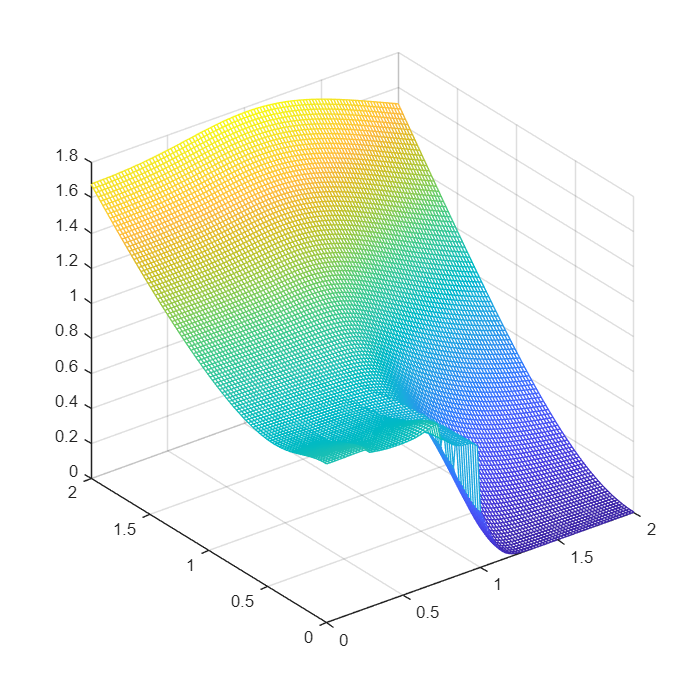


[H, Gamma] = meshgrid(h, gamma);
% disp(d2F)
mesh(H, Gamma, real(d2F))



% imagesc(h, gamma, real(d2F))
% disp(['\gamma = ',num2str(gamma),' h = ',num2str(h),' Thermal Meissner stiffness: d2F = ',num2str(d2F)]);
% 本征值
% eigvals = eigs(H, 5, 'smallestreal');
% disp('最低5个本征值:');
% disp(eigvals);
% 
% H_full = full(H);
% plot(eig(H_full),'.')
function H = Quantum_XY_Hamiltonian(N, Jx, Jy, M_Field, boundarycond, varargin)
    % 一维量子XY自旋链哈密顿量 (自旋1/2)
    % 输入:
    %   N      : 自旋链长度（格点数）
    %   J      : 耦合常数（标量）
    %   periodic : 是否使用周期性边界条件 (true/false)
    % 输出:
    %   H      : 哈密顿量矩阵 (2^N × 2^N，稀疏矩阵格式)

    % Pauli矩阵（自旋1/2算符）
    Sx = [0, 1;  1, 0] / 2;  % S^x = σ^x/2
    Sy = [0, -1i; 1i, 0] / 2;  % S^y = σ^y/2
    Sz = [1, 0; 0, -1] / 2;

    % 初始化哈密顿量为稀疏矩阵
    dim = 2^N;
    H = sparse(dim, dim);
    

    % 生成所有相邻格点对
    if strcmp(boundarycond, "PBC")
        neighbors = [ (1:N)', [2:N,1]' ];  % 周期性边界
        phi = 0;
    elseif strcmp(boundarycond, "OBC")
        neighbors = [ (1:N-1)', (2:N)' ];  % 开边界
    elseif strcmp(boundarycond, "TwistBC")
        neighbors = [ (1:N)', [2:N,1]' ];  % 周期性边界
        phi = varargin{1};
    end

    % 向量化计算所有相互作用项
    for kk = 1:size(neighbors,1)
        ii = neighbors(kk,1);
        jj = neighbors(kk,2);
        
        % 计算 S_i^x S_j^x + S_i^y S_j^y 项
        if kk < N
            term = Jx * ( kron_multiple(Sx, ii, N) * kron_multiple(Sx, jj, N)) + ...
                   Jy * ( kron_multiple(Sy, ii, N) * kron_multiple(Sy, jj, N));
        elseif strcmp(boundarycond, "TwistBC")
            term = exp(1i * phi) * Jx * ( kron_multiple(Sx, ii, N) * kron_multiple(Sx, jj, N)) + ...
                   exp(1i * phi) * Jy * ( kron_multiple(Sy, ii, N) * kron_multiple(Sy, jj, N));
        elseif strcmp(boundarycond, "PBC")
            term = Jx * ( kron_multiple(Sx, ii, N) * kron_multiple(Sx, jj, N)) + ...
                   Jy * ( kron_multiple(Sy, ii, N) * kron_multiple(Sy, jj, N));
        end
        
        H = H - term;  % 累加到哈密顿量
    end

    for ii = 1:N
        H = H + M_Field * kron_multiple(Sz, ii, N);
    end
    H = full(H);
end

function M = kron_multiple(A, pos, N)
    % 快速计算多体系统中单个位置为A的张量积
    % 输入:
    %   A   : 2×2矩阵（当前位算符）
    %   pos : 作用位置 (1到N)
    %   N   : 总格点数
    %   I   : 2×2单位矩阵
    % 输出:
    %   M   : 2^N × 2^N 稀疏矩阵
    
    % 构造位置掩码（向量化实现）
    left = prod(2.^max(0,pos-1));     % 左侧维度
    right = prod(2.^max(0,N-pos));    % 右侧维度
    
    % 利用Kronecker积性质加速计算
    M = kron(speye(left), kron(A, speye(right)));
end


function Z = partition_function_with_twist(H, beta)
    % 计算能量扭曲边界条件下的配分函数
    % H: 哈密顿量，L: 系统尺寸，beta: 逆温度，lambda: 扭曲参数
    
    % 扭曲边界条件算符 U = exp(i*lambda*L*H)
    % U = expm(1i * lambda * L * full(H));
    
    % 配分函数 Z = Tr(exp(-beta H) U)
    rho = expm(-beta * H); % 密度矩阵
    Z = trace(rho * U);
    % Z = trace(rho);
end


function D_Q = thermal_Meissner_stiffness(H, L, beta, delta_lambda)
    % 数值计算热Meissner刚度 D^Q = (1/2L) * d²F/dλ²|λ=0
    % 使用中心差分法求二阶导数
    
    % 自由能 F(λ) = -log(Z(λ))/beta
    free_energy = @(lambda) -log(partition_function_with_twist(H, beta))/beta;
    
    % 二阶导数近似
    d2F = (free_energy(delta_lambda) - 2*free_energy(0) + free_energy(-delta_lambda)) / (delta_lambda^2);
    
    D_Q = d2F / (L * 2) ;
end